# `Armadura Simples`

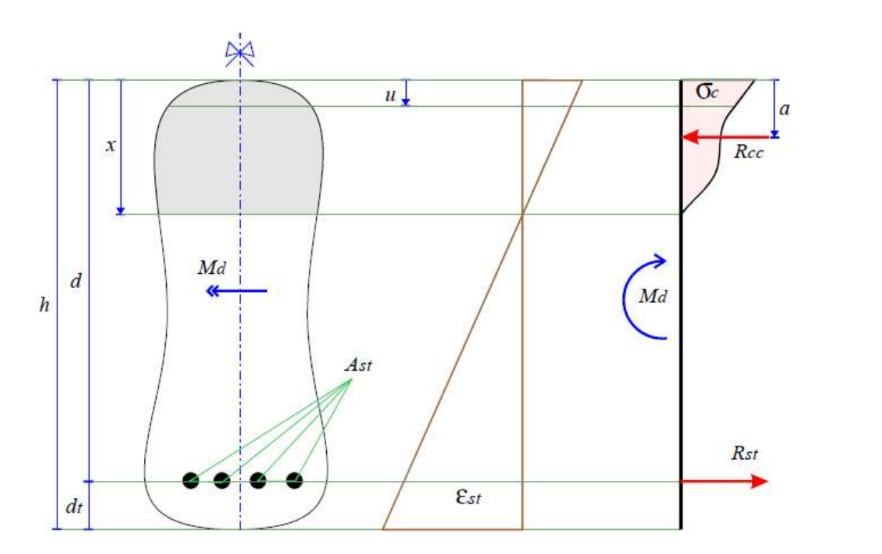

## `Problema de Dimensionamento`

`Primeiro definimos o tipo de concreto e suas especificações`

clear all;
C = 20;
fck = 20000000; %pa
n_c = eta(C);

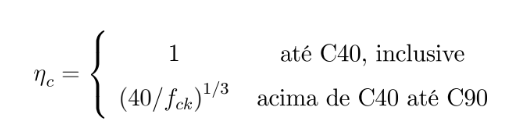

Sigma_cd = n_c*0.85*fck/1.4; 

%Função ec2(fck,C) 
e_c2 = ec2(fck,C);

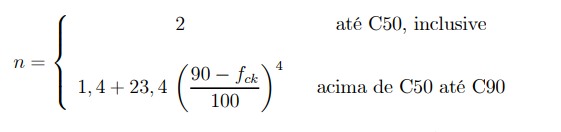

%Função n(fck,C)
n_concreto = n(fck,C);

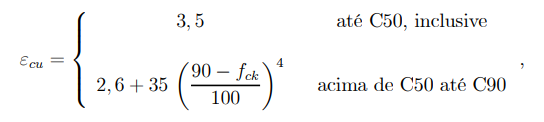

%Função ecu(fck,C)
e_cu = ecu(fck,C);

%Função kxlim(C),
%ajustar função para verificar se k_x 3-4 é menor caso
%positivo trocar 
kx_lim = kxlim(C);

## `Atacando o Problema`

`O seguinte problema possui como icógnitas ``x`` e ``Ast` ` que são respectivamente a posição da linha neutra e Área da Seção da Armadura inferior. `

### `Definição da Propriedade da Viga`

`Consideramos para esse exercício uma seção transversal Retangular, caso necessário mudar a Seção será necessário mudar nas respectivas Fórmulas`

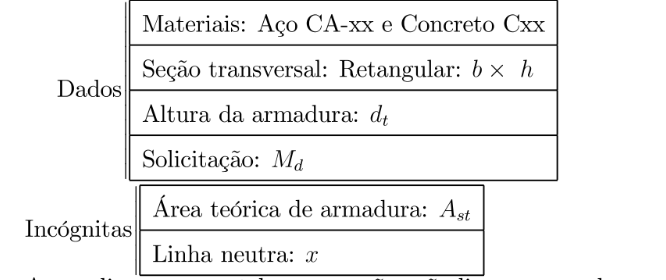

% Área (m)
b = 0.20;
h = 0.44;

% Altura da Armadura (m)
diameter_st = 5*10^-3;
dt = 0.04;
d = h-dt;
% Momento Fletor de Cálculo (kN.m)
Md = 154000;

`Trabalharemos com as seguinte equações não lineares:`

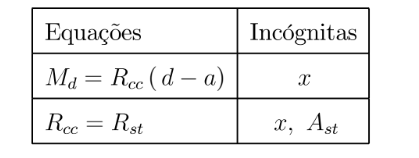

Para solucionar essa equação, utilizaremos o método da bissecção para ober a raíz da função:

## 

No intervalo,** [0,x_lim]**

**Primeiro Passo:** é definir as resultantes por Partes e os seus respectivos domínios a depender do polo

%Definição dos Domínios
%por Simplicidade adotaremos por exemplo,xlim 2a-2b como xlim2b, ou seja, sempre o
%último domínio define a variável

xlim2b = d*e_c2/(e_c2 + 10);
xlim3 = d*e_cu/(e_cu + 10);
xlim = d*kx_lim;

%Rcc (Sigma_cd,b,d,e_c2,e_cu, n_concreto,x,xlim2b,xlim3);

#### `Analogamente, `

## 

## 

## 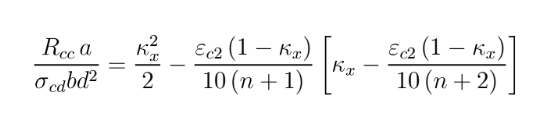

## 

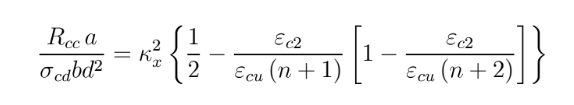

%Rcca (Sigma_cd,b,d,e_c2,e_cu, n_concreto,x,xlim2b,xlim3,xlim);

`Solução da Equação`

f= @(x) Md - Rcc (Sigma_cd,b,d,e_c2,e_cu,n_concreto,x,xlim2b,xlim3)*d + Rcca (Sigma_cd,b,d,e_c2,e_cu, n_concreto,x,xlim2b,xlim3,xlim);
%checar se f(x_lim)< 0, caso positivo, não entrar na bissecção e dizer que
%é impossível, utilizar esse código para calcular altura mínima.

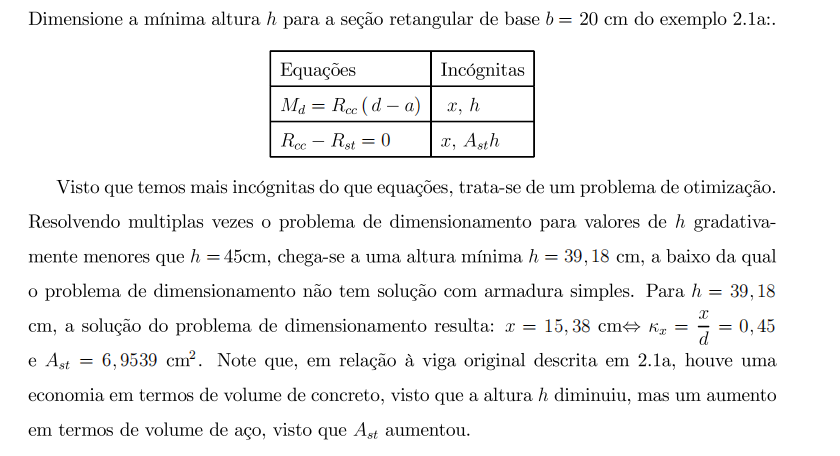

`Aplicando o Método da Bissecção`

% Definir a tolerância e o número máximo de iterações
tolerance = 1e-12;
max_iter = 1000;
xi = 0;
xf = d;

% Implementar o método da bissecção
for iter = 1:max_iter
    % Calcular o ponto médio
    c = (xi + xf) / 2;
    
    % Avaliar f(a), f(b) e f(c)
    fa = f(xi);
    fb = f(xf);
    fc = f(c);
    
    % Verificar a condição de parada
    if abs(fc) < tolerance || (xf - xi) / 2 < tolerance
        linha_neutra = c;
        fprintf('x = %.6f cm', linha_neutra*100);
        
        break;
    end
    
    % Atualizar os valores de a e b
    if fa * fc < 0
        xf = c; % A raiz está entre a e c
    else
        xi = c; % A raiz está entre c e b
    end
end

x = 27.377503 cm

if iter == max_iter
    fprintf('O método atingiu o número máximo de iterações\n');
end


Verificando a Resposta

%Verificando se está dentro dos Limites
k = linha_neutra/d;
PoloI=false;
PoloII =false;
Dupla = false;
if k < kx_lim && k > 0
    fprintf('O dimensionamento é possível \n');

    %Verificar o domínio
    
    if linha_neutra < xlim2b
       fprintf('Domínio 2a - Polo I\n');
       PoloI = true;
    elseif linha_neutra >= xlim2b && linha_neutra < xlim3
       fprintf('Domínio 2b - Polo I\n');
       PoloI = true;
    else
       fprintf('Domínio 3 - Polo II\n');
       PoloII = true;
    end

else    
    fprintf('Considere a possibilidade de uma armadura Dupla \n');
    Dupla = true;
end

Considere a possibilidade de uma armadura Dupla 


A segunda Parte do Problema consiste em Calcular a Área da Secção 

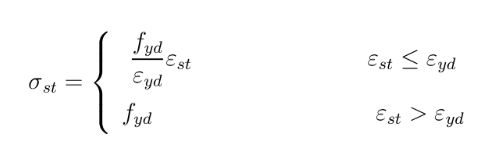

### 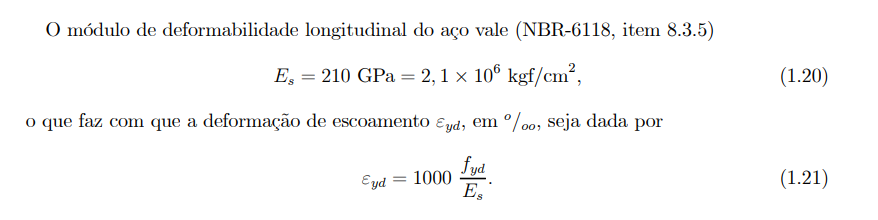

%Logo determinamos pela Segunda Equação Rcc = Rst, Ast = Rcc/sigma_st
  %definido na função sigma_sc(f_yd,e_yd,x,xlim3,xlim,e_cu,d,dc)
    %Area da Seção
    %Constantes
    f_yk = 500;
    f_yd = f_yk /1.15 *10^6;
    e_yd = 1000*f_yd/(210*10^9); %depende do material, esse é o aço C50, 500 MPa, troque os valores
    diameter_sc = 16*10^-3;
    dc = 0.04;

if Dupla == false
    A_st = 10^4*Rcc (Sigma_cd,b,d,e_c2,e_cu, n_concreto,linha_neutra,xlim2b,xlim3)/sigma_st(f_yd,e_yd,linha_neutra,xlim3,xlim,e_cu,d);
    
    fprintf('A_st = %.6f cm^2', A_st);
end

# `Armadura Dupla`

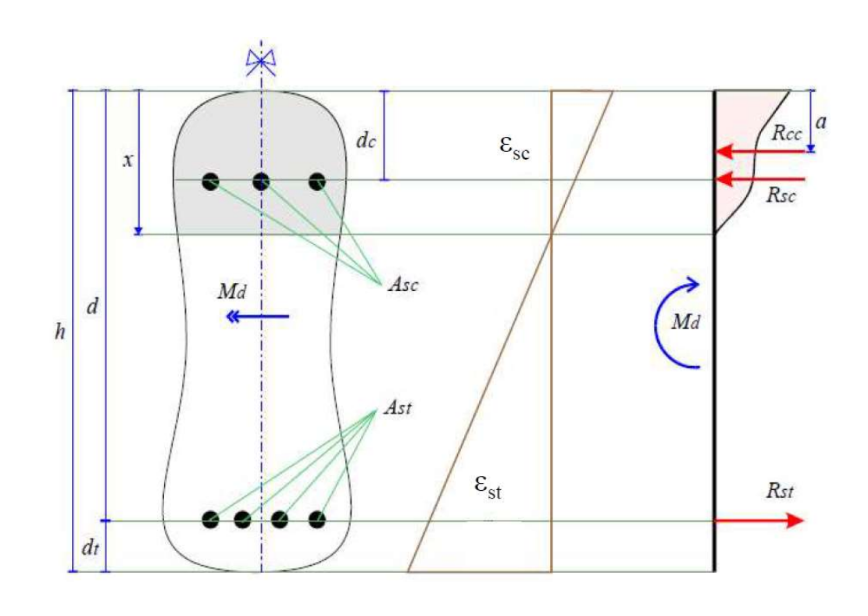

A equação se particulariza:

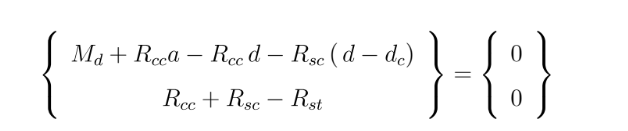

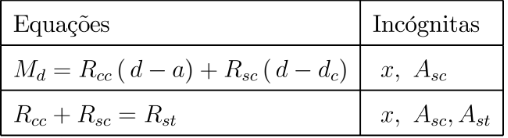

Nesse ponto deve seguir o Fluxograma a seguir:

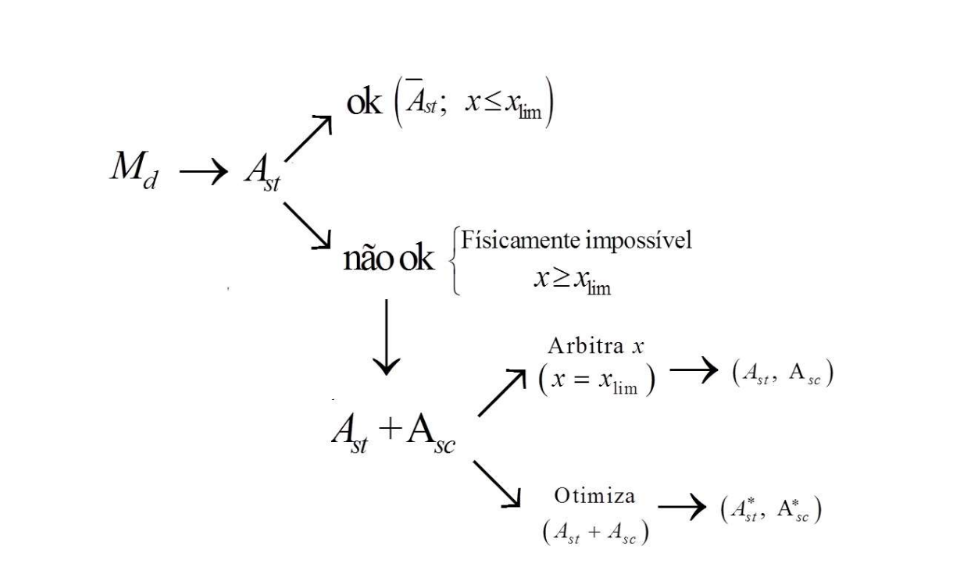

Como a primeira parte do código já verifica a Armadura sem considerar Simples, vamos verificar o segundo caso

Definimos os parâmetros da segunda Armadura e o Cálculo da resultante de compressão do aço

          

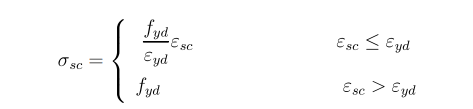

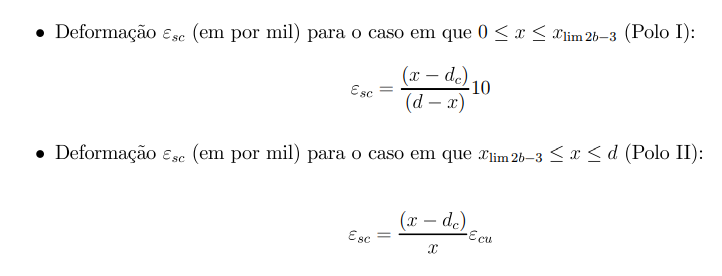

A forma de realizar é testar valores no intervalo:

Primeira parte é isolar Asc e fazer em função de x

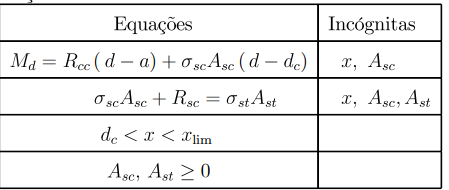

   Asc = @(x) (Md - Rcc (Sigma_cd,b,d,e_c2,e_cu, n_concreto,x,xlim2b,xlim3) * d + Rcca(Sigma_cd, b, d, e_c2, e_cu, n_concreto, x, xlim2b, xlim3, xlim))/(sigma_sc(f_yd,e_yd,x,xlim3,xlim,e_cu,d,dc)*(d-dc));

Definimos então Ast em função de x e Asc

   Ast = @(x) (sigma_sc(f_yd,e_yd,x,xlim3,xlim,e_cu,d,dc) * Asc(x) + Rcc (Sigma_cd,b,d,e_c2,e_cu, n_concreto,x,xlim2b,xlim3))/sigma_st(f_yd,e_yd,x,xlim3,xlim,e_cu,d);

Realizando os Testes

   f = @(x) (Asc(x) + Ast(x));
   i_min= xlim;
   min = Inf;
    for i= dc:0.0000001:xlim
        test = f(i);
        if (test <= min) && (Asc(i) > 0) && (Asc(i) > 0)
            min=test;
            i_min=i;
        end
    end
  fprintf("Asc = %.6f cm^2\n", Asc(i_min)*10^4);

Asc = 2.488165 cm^2


  fprintf("Ast = %.6f cm^2\n", Ast(i_min)*10^4);

Ast = 10.627349 cm^2


  n_st = Ast(i_min)/(pi*(diameter_st/2)^2)

n_st = 54.1246

  n_sc = Asc(i_min)/(pi*(diameter_sc/2)^2)

n_sc = 1.2375